# Autocorrelation method

A. Rey MSE 2022 MA-StatDig

## Exemple with a sinus signal

We want to modelize with a all pole second order model:

$H(z)=\frac{b(0)}{1+a(1)z^{-1}+a(2)z^{-2}$   (1)

The normal equation are:

$\left[\matrix{r_x(0) & r_x(1) \cr r_x(1) & r_x(0)}\right]\left[\matrix{a(1) \cr a(2)}\right] = \left[\matrix{r_x(1) \cr r_x(2)} \right]$  (2)


$$R_x\overline{a}_p = -r_x$$


## Theoric value of the autocorrelation and Prony computed all pole filter

The theoric autocorrelation of $x(n)$are given by (see example 3.3.1 in chapter 3):

$r_x(k) = E\{x(n)x(n-k)\} = \lim_{N\rightarrow \infty}\frac{1}{N}\sum_{n=k}^Nx(n)x(n-k)=\frac{1}{2}A^2\cos(k\omega_0)$   (3)

Try several number od samplees $N$, for a multiple of the period length (ex 40) and also 38, 42 or 55. The result will be very different to the theory.

N = 55;
N0 = 20;
A = 1;
n = 0:N-1;
x = A*sin(2*pi/N0 * n);
x = x(:)

x =          0
    0.3090
    0.5878
    0.8090
    0.9511
    1.0000
    0.9511
    0.8090
    0.5878
    0.3090



dn = zeros(1,N);
dn(1) = 1;
p = 2;

If we compare with the theoric values of the autocorrelation (3) we have the values $r_x(k)$ for $k = 0,1,2$:

rxth = 0.5*A.^2*cos((0:2) * 2*pi/N0)

rxth =     0.5000    0.4755    0.4045


Rxth = [rxth(1) rxth(2); rxth(2) rxth(1)]

Rxth =     0.5000    0.4755
    0.4755    0.5000



apth = [1; -inv(Rxth)*[rxth(2);rxth(3)]]

apth =     1.0000
   -1.9021
    1.0000


Ep = rxth(1) + apth(2)*rxth(2) + apth(3)*rxth(3)

Ep = 5.5511e-17

pth = roots(apth)

pth =    0.9511 + 0.3090i
   0.9511 - 0.3090i


As expected the norm of the poles is $= 1$, that produces an impulse response $h(n) = x(n)$.

Norm_pth = abs(pth)

Norm_pth =     1.0000
    1.0000


H_th = tf(x(2),apth',1)

H_th =
 
        0.309
  -----------------
  z^2 - 1.902 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.



h_th = impz(x(2), apth, length(x))'

h_th =     0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000


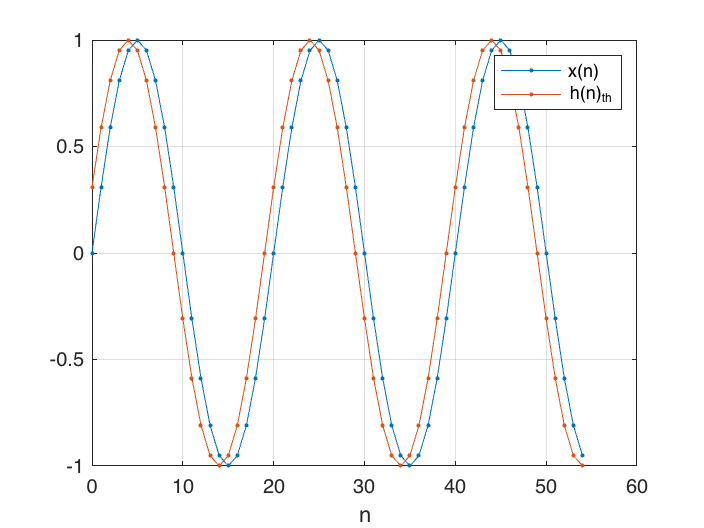


figure
plot(n, x, '.-', ...
     n, h_th, '.-');
grid;
legend('x(n)', 'h(n)_{th}')
xlabel('n')

## Autocorrelation method to estimate the all pole filter

The estimation of the autocorrelation as the Prony Autocorrelation method is different:

$\hat{r}_x(k)=\frac{1}{N}\sum_{n=k}^Nx(n)x(n-k)\qquad ; k \ge  0$    (4)

To estimate the autocorrelation with a finite record of N points we use the convolution matrix:

X = convmtx(x,p+1);
Xp = X(1:N+p-1, 1:p)

Xp =          0         0
    0.3090         0
    0.5878    0.3090
    0.8090    0.5878
    0.9511    0.8090
    1.0000    0.9511
    0.9511    1.0000
    0.8090    0.9511
    0.5878    0.8090
    0.3090    0.5878


Rx = Xp' * Xp *1/N

Rx =     0.4909    0.4582
    0.4582    0.4909


rx = Xp'*X(2:N+p,1) / N

rx =     0.4582
    0.3824


ap = [1; -inv(Rx)*[rx(1);rx(2)]]

ap =     1.0000
   -1.6027
    0.7170


Error:


$$\epsilon_p = r_x(0)+\sum_{k=1}^pa_p(k)r_x^*(k)$$
 

err = (Rx(1) + rx'*ap(2:3))*N

err = 1.6882

bq0 = sqrt(err)

bq0 = 1.2993

The poles of the transfer function are:

poles = roots(ap)

poles =    0.8014 + 0.2735i
   0.8014 - 0.2735i


We see the norm of  the poles are $< 1$, filter is stable but the impulse response $h(n)$ is the damped sinus...

Norm_p = abs(poles)

Norm_p =     0.8468
    0.8468


H_acm = tf(bq0,ap',1)

H_acm =
 
          1.299
  ---------------------
  z^2 - 1.603 z + 0.717
 
Sample time: 1 seconds
Discrete-time transfer function.



h_acm = impz(bq0, ap, length(x))'

h_acm =     1.2993    2.0825    2.4060    2.3630    2.0622    1.6108    1.1031    0.6130    0.1916   -0.1325   -0.3497   -0.4655   -0.4953   -0.4601   -0.3823   -0.2828   -0.1791   -0.0843   -0.0067    0.0497    0.0844    0.0997    0.0993    0.0876    0.0692    0.0482    0.0275    0.0096   -0.0044   -0.0139   -0.0191   -0.0207   -0.0194   -0.0163   -0.0122   -0.0079   -0.0039   -0.0006    0.0019    0.0034    0.0041    0.0042    0.0037    0.0030    0.0021    0.0012    0.0005   -0.0001   -0.0005   -0.0008


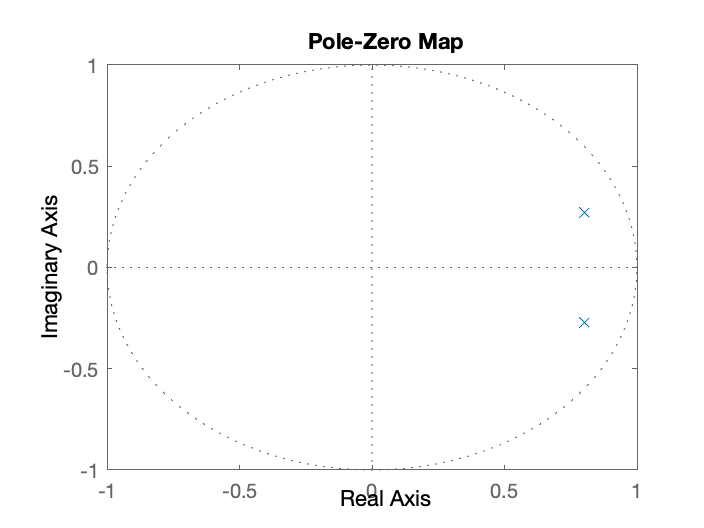


figure
%plot(real(poles), imag(poles), 'o')
%axis([-1 1 -1 1])
pzplot(H_acm)